# Simulate Linear Inverted Pendulum Model (LIPM) with Simple Foot Change Controller

Create body trajectory based on the LIPM. We assume 

- The walking pattern is symmetric 

- There are no disturbances

The piece of trajectory used to generate a walking pattern can be found by using the [LIPM app](matlab: run('applicationLIPM')) or by the `findInitialConditions` function provided in this script. This function finds initial condition for creating symmetric piece of trajectory.  

Most of the math comes from [The 3D Linear Inverted Pendulum Mode: A Simple modeling for a biped walking pattern generation](https://www.cs.cmu.edu/~hgeyer/Teaching/R16-899B/Papers/KajiitaEA01IEEE_ICIRS.pdf) by Kajita et al.

*Copyright 2019 The MathWorks, Inc.*

## Setup

### Set Variables and Model Initial Conditions

Toggle `animateOn` to be false if you would like to speed up the script and not see the animation. 

animateOn = true; 
xTorso = 0.12; % x distance from body to foot， 0.12 is the original value
g = 9.807; 
Ts = 0.005; %sample time (s)

The height of the robot when standing straight is defined as `zRobot`. The height of the pendulum (and hence the height at which we will make the robot walk at) is defined by `zModel`. 

zRobot = 0.78;
zModel = 0.68;  

We also need to define a swing height for the foot trajectories. This is a design parameter that has no effect at this point outside visualization.

swingHeight = 0.1; % 0.1 

Initial conditions have to create a symmetric trajectory and move in a positive Y direction, starting with a positive initial X position x0. There are two ways to set the initial condition here: 

- Using the set of numbers you found from the application that creates a symmetric trajectory

- Using a parametric set of initial conditions that guarantees symmetric trajectory. The **function **`findInitialConditions`** uses the orbital energy to find the initial conditions**. Take a look at the function and Kajita's paper for more detail. Use the variable `useParametericICs` to switch between the two. The non-parametric conditions are conditions that I found to be symmetric using the application. 

**NOTE:** There are other ways to find the initial condition `y0` for a desired final `yd` and `dyd` (position and velocity). This is included as the `findFootHold` function at the end of this file if you would like to try it. It is the optimization function desribed in Kajita's [The 3D Linear Inverted Pendulum Mode: A Simple modeling for a biped walking pattern generation](https://www.cs.cmu.edu/~hgeyer/Teaching/R16-899B/Papers/KajiitaEA01IEEE_ICIRS.pdf). Yet another way to find the next foot position (and therefore the initial condition) is by using capture point. For capture point dynamics and control, refer to [Bipedal walking control based on Capture Point dynamics](https://www.semanticscholar.org/paper/Bipedal-walking-control-based-on-Capture-Point-Englsberger-Ott/d8b4d3779dc3d6ccfb70d62b7e2c720ce482edf2) by Englsberger et al. 

useParametricICs = true; 

if useParametricICs
    stepLength = 0.2; % half of 0.4?
    dy_mid = 0.06;  % y velocity when y = 0 this is the minimum y velocity
    x0 = 0.12;      % want x0 to be around xTorso 
    [dx0, y0, dy0, tSingleSupport] = findInitialConditions(stepLength, dy_mid, x0, zModel, g, Ts); % also output these values as default, below "else"
else
    tSingleSupport = 1.335;
    x0 = 0.12; 
    dx0 = -0.4501;
    y0 = -0.1; 
    dy0 = 0.3845;
end 

### Create the Linear Inverted Pendulum Model

Create a discrete state-space model of the linear inverted pendulum.

A = [0   1 0    0
    g/zModel 0 0    0
    0    0 0    1
    0    0 g/zModel 0]; 
B = [0 0
     1 0
     0 0
     0 1]; 
C = [1 0 0 0
     0 0 1 0]; 
D = [0 0;0 0]; 

lipm = ss(A,B,C,D); 
lipmD = c2d(lipm, Ts); 

Ad = lipmD.A; 
Bd = lipmD.B;
Cd = lipmD.C;
Dd = lipmD.D;

The initial state `state0` is the initial condition that allows a symmetric trajectory. 

state0 = [x0; dx0; y0; dy0]; 

We want to look at the LIPM's natural dynamics, so the system is not actuated. Hence the input vector `u0` is all zeros.

u0 = [0; 0];

### Save Model Parameters 

Place all the model parameters in a structure allows us to pass them into other functions using a single variable.

modelVars.g = g; 
modelVars.Ts = Ts; 
modelVars.zModel = zModel;
modelVars.Ad = Ad; 
modelVars.Bd = Bd; 
modelVars.Cd = Cd; 
modelVars.Dd = Dd; 
modelVars.tSingleSupport = tSingleSupport; 

Similarly, create a `simStates` structure to keep track of the simulation information and pass it to other functions.

simStates = struct('bodyPos',[],'footPos',[],'timeVec',[]);

### Set Foot Initial Conditions and Number of Steps 

This is the robot standing still with straight legs. Remember that we are making a trajectory for the actual robot and we are using a  simple model to create a trajectory. The trajectory is simply coming from the natrual dynamics of the pendulum (and the initial conditions). We are simply **choosing the next foothold and let the pendulum give us the trajectory. **

**NOTE: **This script assumes the robot makes the left step first. The first two entries below define the starting position of both left and right feet, at offsets of `-xTorso` and `+xTorso`, respectively. Then, the third entry of `footPos` will be for the left foot first, the fourth for the right foot, and so on. Change accordingly depending on which foot is going out first and also which direction it is headed (for this script going in the positive Y direction). 

robotpos0 = [0; 0; zRobot]; 

% Store left and right foothold position (left:odd, right:even)
simStates.footPos(:,end+1) = [-xTorso; 0; 0]; % left foot
simStates.footPos(:,end+1) = [ xTorso; 0; 0]; % right foot

% Set the total number of steps to take
numSteps = 6;

### Initialize Graphics

Graphics objects help us animate the model. 

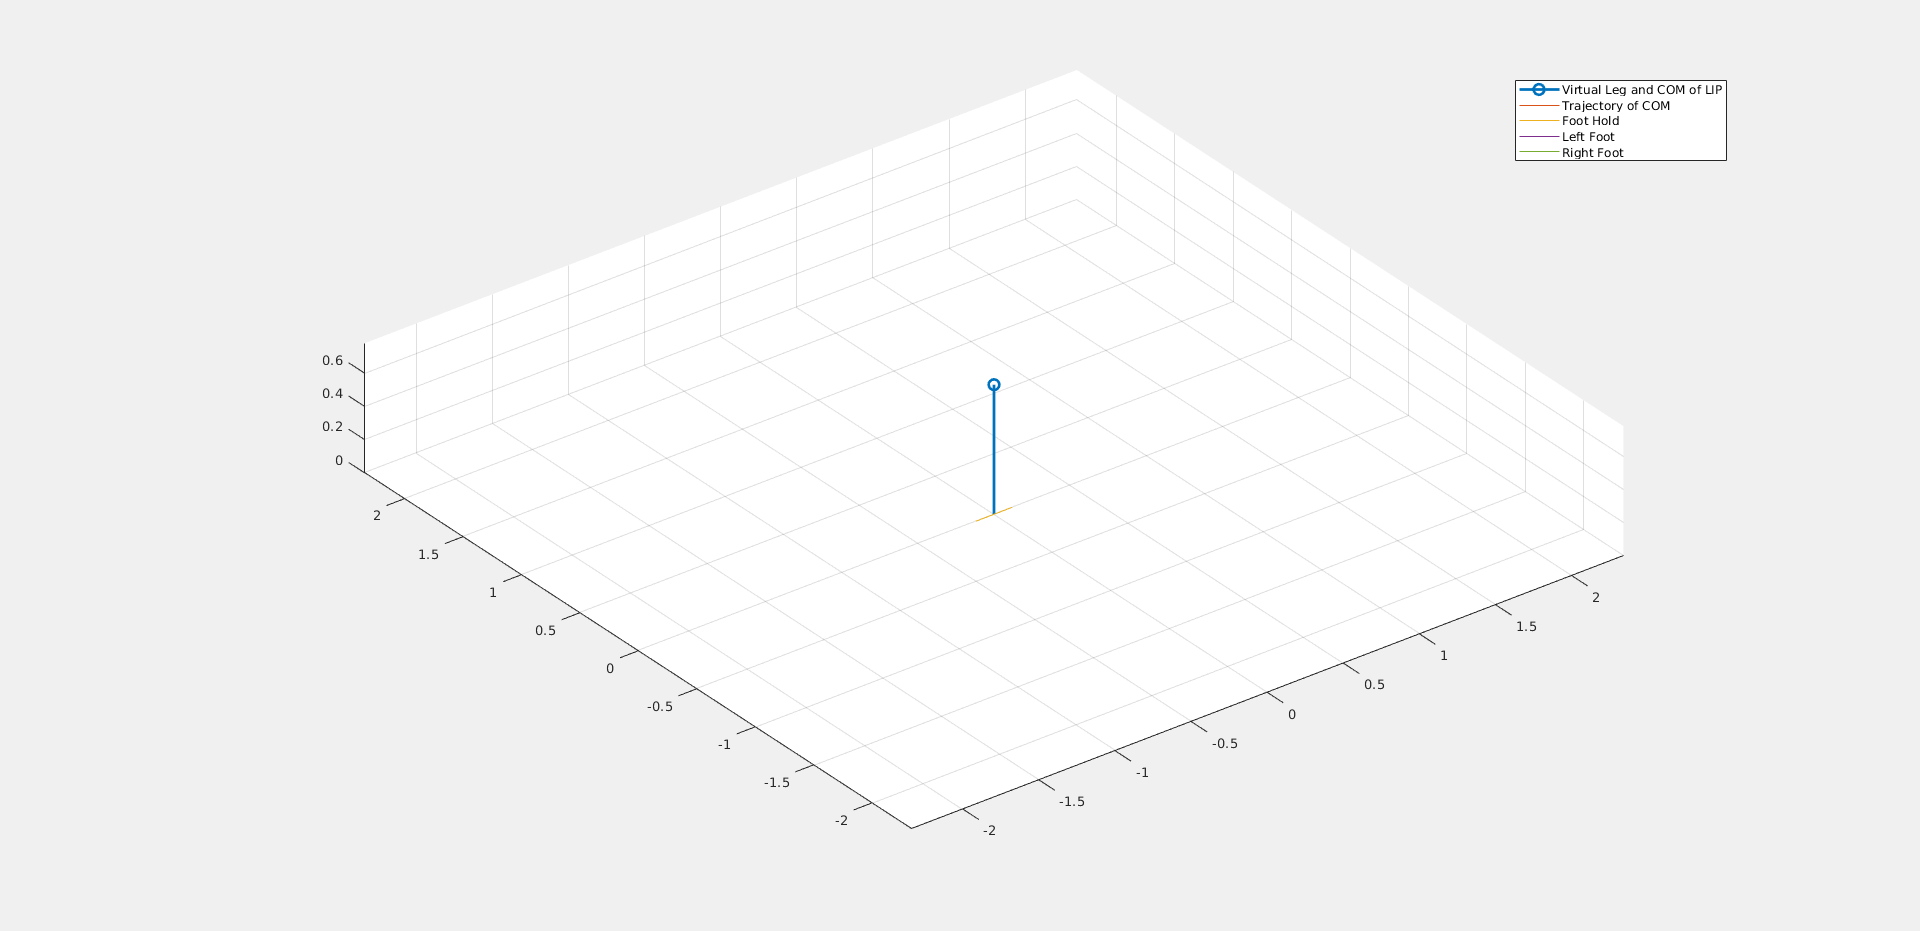

hFig = figure; 
hFig.Visible = 'on'; % for livescript 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
hAx  = axes(hFig); 

% create handles for plots 
hold(hAx, 'on'); 
hLeg  = plot3(hAx,[0,robotpos0(1)],[0,robotpos0(2)],[0,robotpos0(3)],...
                '-o','MarkerIndices',2,'LineWidth',2,'MarkerSize',8); % represents com + leg 
hCom = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents com traj
hLineFootHold = plot3(hAx, simStates.footPos(1,:), simStates.footPos(2,:), simStates.footPos(3,:)); % represents foothold traj
hLineLeftFoot = plot3(hAx, simStates.footPos(1,1), simStates.footPos(2,1), simStates.footPos(3,1));
hLineRightFoot = plot3(hAx, simStates.footPos(1,2), simStates.footPos(2,2), simStates.footPos(3,2));
hold(hAx, 'off'); 

grid(hAx, 'on'); 
view(hAx,3)
axis equal 
hAx.XLim = [-3*zRobot 3*zRobot];
hAx.YLim = [-3*zRobot 3*zRobot]; 
legend(hAx, 'Virtual Leg and COM of LIP','Trajectory of COM', 'Foot Hold', 'Left Foot', 'Right Foot', ...
       'Location', 'northeast');

### Setup variable used in next script

This variable will be used in animateLIPMLocal. This is my way of transferring information from one script to the next. You can stil run the next script without running this one, that script will grab the variable from 'defaultstepinfos'. 

stepinfos = cell(1,numSteps+2);

## Simulation

### Phase 1-1) Move the COM above one foot

This script is used **to create a Center of Mass (COM)** and swing foot trajectory for the robot to follow. So we have to keep in mind that the robot will be standing still at the beginning (`zRobot`), but will have to lower its center of mass (`zModel`) and start moving. The initialization phases are 1-1) Lowering the body and 1-2) Going to the initial condition (`x0`, `y0`, `dx0`, `dy0`) that we set earlier. 

To execute motion, we apply a **cubic polynomial trajectory** through the [`cubicpolytraj`](https://www.mathworks.com/help/robotics/ref/cubicpolytraj.html) function from Robotics System Toolbox. You can replace this with another function to create a different interpolating trajectory.  

**NOTE: **The variable `walkRdyPoints` has a hardcoded value. We command the robot to lower its body and at the same time move toward the right foot because it will be standing on the right foot during phase 1-2). These values are arbitrary and you may feel free to choose your own.

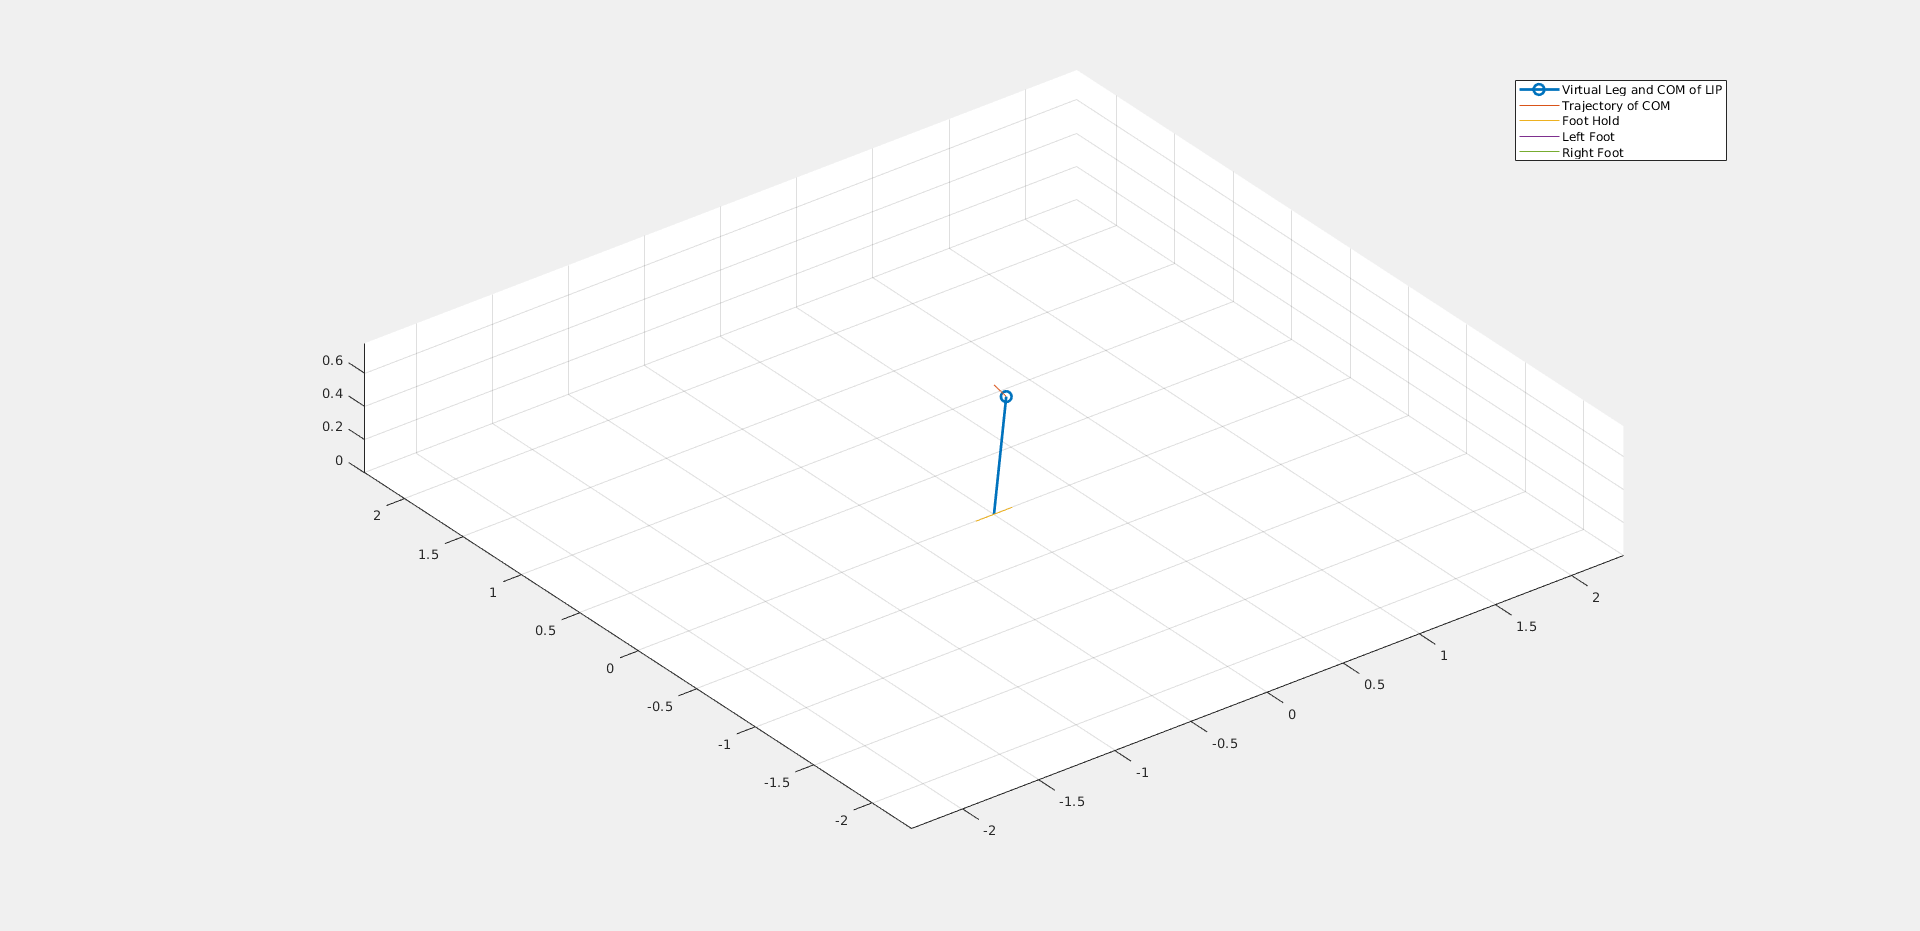

walkRdyPoints = [0      0.67*x0; 
                 0      0      ; 
                 zRobot zModel];  
% Note: We are moving COM to be partly over the right foot

timepoints = [0 1]; % Hard-coded 1 second to move down
timevec = timepoints(1):Ts:timepoints(end)-Ts; 
[q, qd] = cubicpolytraj(walkRdyPoints, timepoints, timevec); 
simStates.bodyPos = [simStates.bodyPos q]; 
simStates.timeVec = [simStates.timeVec timevec]; 

% save data
fhold_x = simStates.footPos(1,1); 
fhold_y = simStates.footPos(2,1); 
stepinfo.index = 1; 
bodystate = [q(1,:); qd(1,:); q(2,:); qd(2,:); q(3,:); qd(3,:)]; % pos wrt world  
relstate = bodystate - [fhold_x; 0; fhold_y; 0; 0; 0]; % save pos wrt foot  
stepinfo.state = relstate;
stepinfo.timevec = timevec; 
stepinfo.mode = 'doublesupport'; 
stepinfo.footplant = [fhold_x; fhold_y; 0]; % state is in absolute position 
stepinfos{1} = stepinfo; 

% update graphics
for idx = 1:size(simStates.bodyPos,2)
    points = [zeros(3,1) simStates.bodyPos(:,idx)]; 
    updateLine(hLeg, points); 
    appendLine(hCom, simStates.bodyPos(:,idx)); 
    if animateOn
        pause(0.005);
    end
end

### Phase 1-2) Make a half step

As mentioned in the previous phase, this phase is for the robot to go to the inital condition we set earlier. Also we have to think about how the swing foot will move at the same time! The swing foot moves its other leg to the next plant position where it will become the new base for the pendulum. The pendulum base is where the robot has its plant foot at.

**NOTE: **The `walkRdyPoints` variable has a hard coded value. This is how far the robot will move its COM to before making the stance transition (right to left or left to right). If you selected the `useParametricICs` option, this corresponds to exactly half the step length.

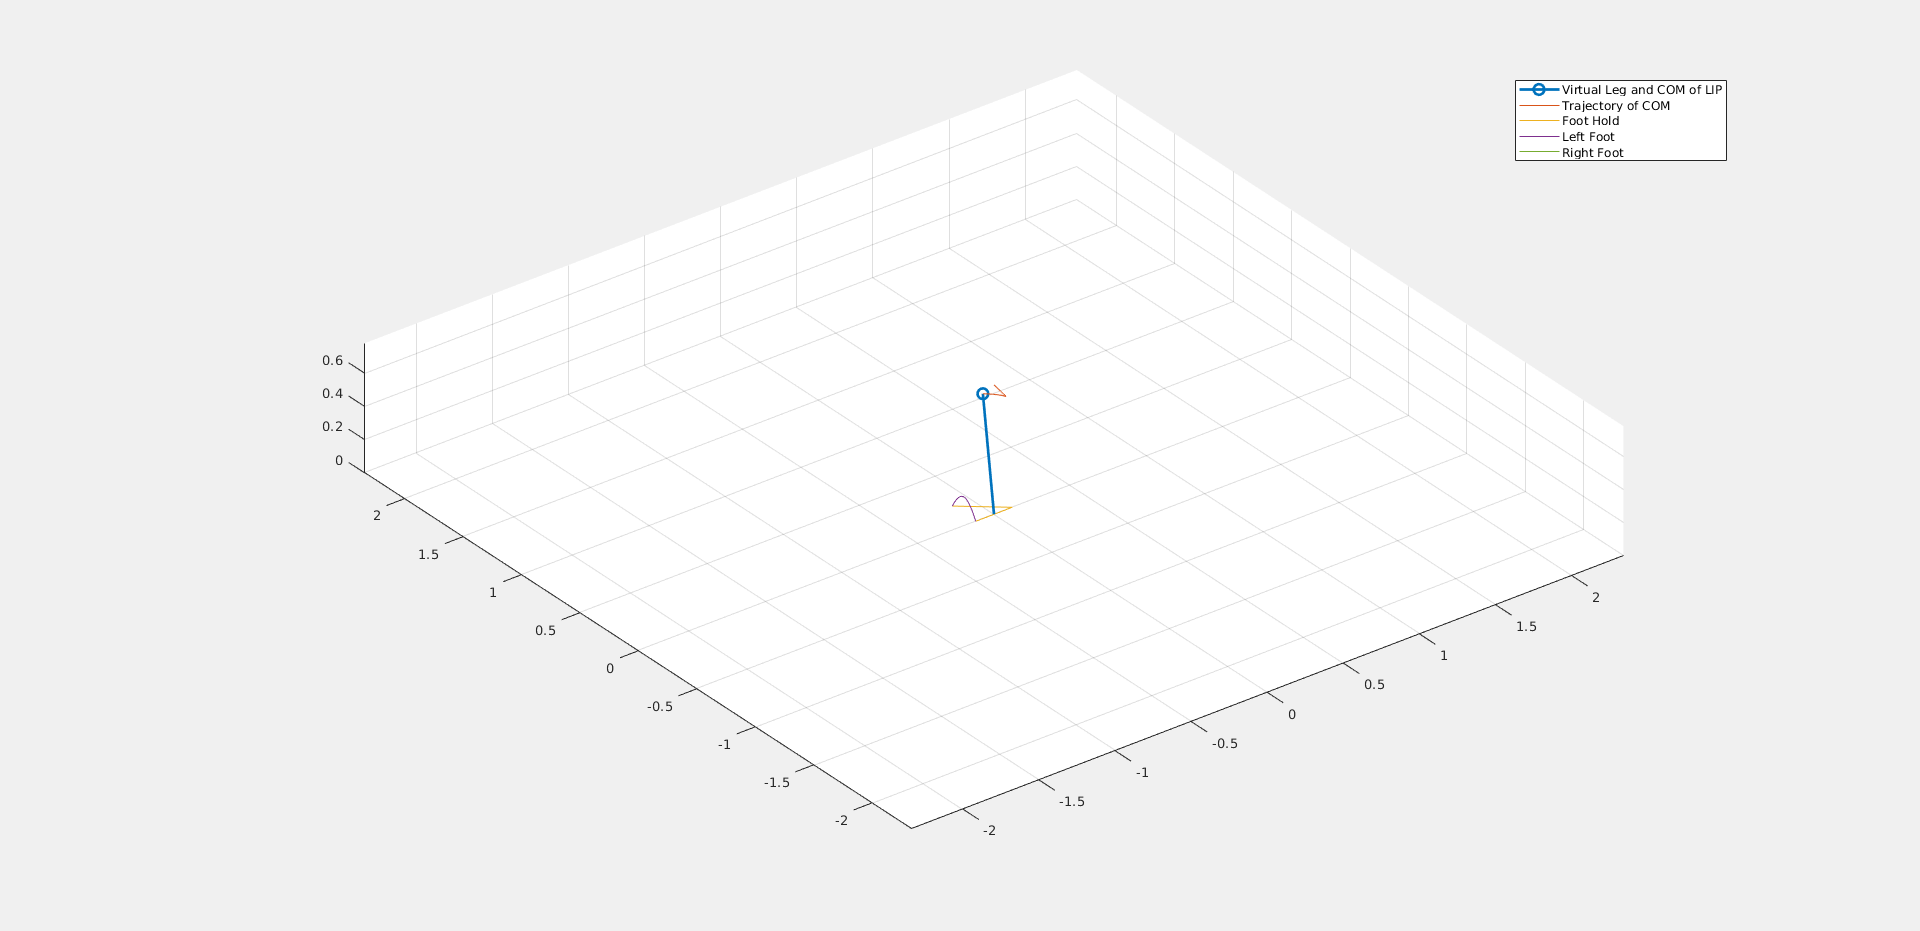

walkRdyPoints(:,end+1) = [0     ; 
                          0.1   ; 
                          zModel];  
% why half step? TODO: 0.1 -> -0.1
yoff = walkRdyPoints(2,3); %0.1
% initial walking footPosition
fhold_x = -x0; %-0.12
fhold_y = -y0 + yoff;%-(-0.1)+ 0.1
simStates.footPos(:,end+1) = [fhold_x; fhold_y; 0]; % left

% make trajectory for the stance foot to walk-initial state
rdyPos1 = walkRdyPoints(:,2); 
rdypos2 = walkRdyPoints(:,3); 
rdyvel1 = [0; 0; 0]; 
rdyvel2 = [dx0; dy0; 0]; 
waypoints = [rdyPos1 rdypos2];
velpoints = [rdyvel1 rdyvel2]; 

timepoints = [1 1.5]; % Hard-coded 0.5 seconds to take a half step
timevec = timepoints(1):Ts:timepoints(end)-Ts; 
[q, qd, qdd] = cubicpolytraj(waypoints, timepoints, timevec, ...
                  'VelocityBoundaryCondition', velpoints); 
simStates.bodyPos = [simStates.bodyPos q]; 
simStates.timeVec = [simStates.timeVec timevec]; 

% make trajectory for the swing foot
swingfootpos0 = simStates.footPos(:,1); 
swingfootpos1 = simStates.footPos(:,3); 
[qswing, dqswing, ddqswing] = getSwingFootTraj(swingfootpos0, swingfootpos1, swingHeight, ...
                                timepoints(1), timepoints(end),Ts); 

% save data
stepinfo.index = 2; 
bodystate = [q(1,:); qd(1,:); q(2,:); qd(2,:); q(3,:); qd(3,:)]; % com info 
relstate = bodystate - [simStates.footPos(1,2); 0; simStates.footPos(2,2); 0; 0; 0]; % relative position  
stepinfo.state = relstate;
stepinfo.timevec = timevec; 
stepinfo.mode = 'singlesupportright'; 
stepinfo.swing = qswing; 
stepinfo.footplant = [simStates.footPos(1,2); simStates.footPos(2,2); 0]; 
stepinfos{2} = stepinfo; 

% update graphics
for idx = 1:size(q,2)
    points = [zeros(3,1) q(:,idx)]; 
    updateLine(hLeg, points); 
    appendLine(hCom, q(:,idx)); 
    % add points to swing foot 
    appendLine(hLineLeftFoot, qswing(:,idx)); 
    if animateOn
        pause(0.005);
    end

end
appendLine(hLineFootHold, [fhold_x; fhold_y; 0])

### Phase 2) Make consecutive steps

This is the core functionality of the walking pattern. Once we have the initial conditions that give us a symmetric trajectory, we can use this to create a pattern. Note how the "stitching" is done using the `changeLeg` function. Since we know the trajectory is going to be symmetric, we place the next foot hold at a mirrored distance away. Then we simulate the model to create the next trajectory. Then the foot hold is changed again after step time `tSingleSupport` has passed. 

Note that this is a simple algorithm assuming a symmetric trajectory! There are other more robust techniques to walk in assymetric patterns.

To clarify the steps:

- `stanceSim`: Model is simulated with the given initial condition for single support time (`tSingleSupport`) to give us the natural trajectory of the LIPM

- `changeLeg`: The next foot hold is found using a simple mirroring method. That gives us new initial conditions `x0` and `y0`, since we changed our foot hold to be the base of pendulum. 

- We set the initial velocities (`dx0` and `dy0`) to be the same as the final velocities (`dxf` and `dyf`) from the previous stance because switching foot changes instantaneously. 

**NOTE 1: **There is no double support phase. The model is always supported by a single foot. We are changing from left stance to right stance instantaneously. Most robots will have double support phase between the two for more stability. The double support phase was omitted to simplify the trajectory. 

**NOTE 2: **The swing foot trajectory is created here just for visualization. The foot trajectory doesn't necessary have to be defined here, as it can be done later when executing the foot motion plan.

fhold_x1 = fhold_x; 
fhold_y1 = fhold_y; 
 
for stp = 1:numSteps  
    % Update foot hold postiions
    fhold_x0 = fhold_x1;
    fhold_y0 = fhold_y1;
    
    % Simulate stance LIPM for single support time duration
    [states, timevec, simStates] = stanceSim(fhold_x0, fhold_y0, state0, u0, modelVars, simStates);
    
    % Save Step Info at each step 
    index = stp + 2; 
    stepinfo.index = index; 
    savestate = [states; repmat([zModel; 0],[1 size(states,2)])]; % Add Z and dZ states
    stepinfo.state = savestate; 
    stepinfo.footplant = [fhold_x0; fhold_y0; 0]; 
    stepinfo.timevec = timevec; 
    if rem(stp,2) > 0
        stepinfo.mode = 'singlesupportleft';
    else
        stepinfo.mode = 'singlesupportright';
    end     
    
    % change leg according to control law 
    [state0, fhold_x1, fhold_y1] = changeLeg(states(:,end), simStates);
    simStates.footPos(:,end+1) = [fhold_x1; fhold_y1; 0];
    
    % define swing foot trajectory with new leg position 
    [q, dq, ddq] = getSwingFootTraj(simStates.footPos(:,end-2), simStates.footPos(:,end), ...
        swingHeight,timevec(1), timevec(end), Ts); 
    stepinfo.swing = q; 
    
    % simulate stance
    for idx = 1:size(states,2)
        state1 = states(:,idx); 
        meas1 = Cd*state1 + Dd*u0; 
        
        bodypos = [fhold_x0 + meas1(1);
                   fhold_y0 + meas1(2);
                   zModel]; 
        % animate stance leg and COM traj 
        points = [fhold_x0, bodypos(1);
                  fhold_y0, bodypos(2);
                  0,        bodypos(3)]; 
        updateLine(hLeg, points)
        appendLine(hCom, bodypos); 
        
        % animate swing leg 
        if rem(stp,2) > 0
            appendLine(hLineRightFoot, q(:,idx))
        else
            appendLine(hLineLeftFoot, q(:,idx))
        end
        if animateOn
            pause(0.005);
        end
    end 
    % update graphics: change leg
    % animate body/foot with new foothold
    points = [fhold_x1, bodypos(1);
              fhold_y1, bodypos(2);
              0,        bodypos(3)]; 
    updateLine(hLeg, points)
    appendLine(hLineFootHold, [fhold_x1; fhold_y1; 0])
    if animateOn
        pause(0.005); 
    end
    
    % save the data 
    stepinfos{stp+2} = stepinfo;  
end

## Helper Functions  

Find initial condition using orbital energy of the stance dynamics and ensuring a symmetric trajectory. `dy_mid` is the desired Y velocity at the midpoint of the trajectory segment, when `y = 0`. 

This is something I made to make a symmetric trajectory. Please feel free to explore and see how others do it! The two papers are good startingn points: [The 3D Linear Inverted Pendulum Mode: A Simple modeling for a biped walking pattern generation](https://www.cs.cmu.edu/~hgeyer/Teaching/R16-899B/Papers/KajiitaEA01IEEE_ICIRS.pdf) by Kajita et al. and [Bipedal walking control based on Capture Point dynamics](https://www.semanticscholar.org/paper/Bipedal-walking-control-based-on-Capture-Point-Englsberger-Ott/d8b4d3779dc3d6ccfb70d62b7e2c720ce482edf2) by Englsberger et al.

function [dx0, y0, dy0, tsinglesupport] = findInitialConditions(stepLength, dy_mid, x0, zModel, g, Ts)

    Tc = sqrt(zModel/g); 
    % Desired midstance y state
    y_mid = 0;
    % Corresponding orbital energy is
    E = -g/(2*zModel)*y_mid^2 + 0.5*dy_mid^2; 
    
    y0 = -stepLength/2;
    % finding dy0 from midstance energy level 
    dy0 = sqrt(2*(E+g/(2*zModel)*y0^2));
    
    % using relationship between final body state and initial body state,
    % we can find time it will take to reach midstance given final velocity
    % (dy = dy_mid) and final position (which is y = 0 at midstance) 
    tsinglesupport = 2*asinh(stepLength/2/(Tc*dy_mid))*Tc;
    tsinglesupport = floor(tsinglesupport/Ts)*Ts; % should be divisible by sample time 

    % also using relationship between final body state and initial body
    % state. We already know time it will take to reach midstance. 
    tf = tsinglesupport/2; 
    dx0 = -x0/Tc * sinh(tf/Tc) / cosh(tf/Tc);
end

Simulates a walking stance

function [states, timeVec, simStates] = stanceSim(fhold_x, fhold_y, state0, u0, modelVars, simStates)

    % Unpack variables
    Ts = modelVars.Ts;
    Ad = modelVars.Ad;
    Bd = modelVars.Bd;
    
    % Define time vector
    tInitial = simStates.timeVec(end) + modelVars.Ts; % don't let time overlap
    tFinal   = tInitial + modelVars.tSingleSupport; 
    timeVec  = tInitial:Ts:tFinal; 

    % Simulation loop
    nSteps = numel(timeVec); 
    states = zeros(size(state0,1),nSteps);  
    states(:,1) = state0; 
    for idx = 1:nSteps-1
        states(:,idx+1) = Ad*states(:,idx) + Bd*u0;
    end
    
    % Update the simStates structure
    simStates.timeVec = [simStates.timeVec timeVec(1:end-1)];
    newStates = [states(1,2:end)+fhold_x; states(3,2:end)+fhold_y; modelVars.zModel*ones([1 nSteps-1])];
    simStates.bodyPos = [simStates.bodyPos newStates];
end

Changes leg by "flipping" the pendulum about the prescribed state

function [state0, fhold_x, fhold_y] = changeLeg(state1,simStates)  
    % previous final states 
    xf  = state1(1); 
    dxf = state1(2); 
    yf  = state1(3); 
    dyf = state1(4); 

    % use simple control law (mirroring)
    x0 = -xf; 
    y0 = -yf; 
    dx0 = dxf; 
    dy0 = dyf; 
    state0 = [x0; dx0; y0; dy0]; 

    % new foothold
    fhold_x = simStates.bodyPos(1,end) - x0; 
    fhold_y = simStates.bodyPos(2,end) - y0;
end 

Adds points to a graphics line object

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end

Utility function that uses optimization to find capture points (currently not used). For more information, refer to [The 3D Linear Inverted Pendulum Mode: A Simple modeling for a biped walking pattern generation](https://www.cs.cmu.edu/~hgeyer/Teaching/R16-899B/Papers/KajiitaEA01IEEE_ICIRS.pdf) by Kajita et al.

function xi = findFootHold(xd, vd, vi, mvar)
    g = mvar.g; zModel = mvar.zModel; tSingleSupport = mvar.tSingleSupport; 
    a = 1; % weight for distance
    b = 1; % weight for velocity
    
    Tc = sqrt(zModel/g); 
    CT = cosh(tSingleSupport/Tc); 
    ST = sinh(tSingleSupport/Tc); 
    DT = a*CT^2 + b*(ST/Tc)^2; 
    
    xi = (a*CT*(xd - ST*Tc*vd) + b*ST/Tc*(vd-CT*vi))/DT; 
end